# DC_LAB3_AngularVelocity

addpath("plot\");
addpath("Linearization\");
addpath("Modeling\");

## 1. Obtain Static Property & Mapping Linearization  

filename='../data/Static/Static_iter';
% STEP 1. 
iter=5 % <- Modify here

iter = 5

Cannot find a file: ../data/Static/Static_iter5.out


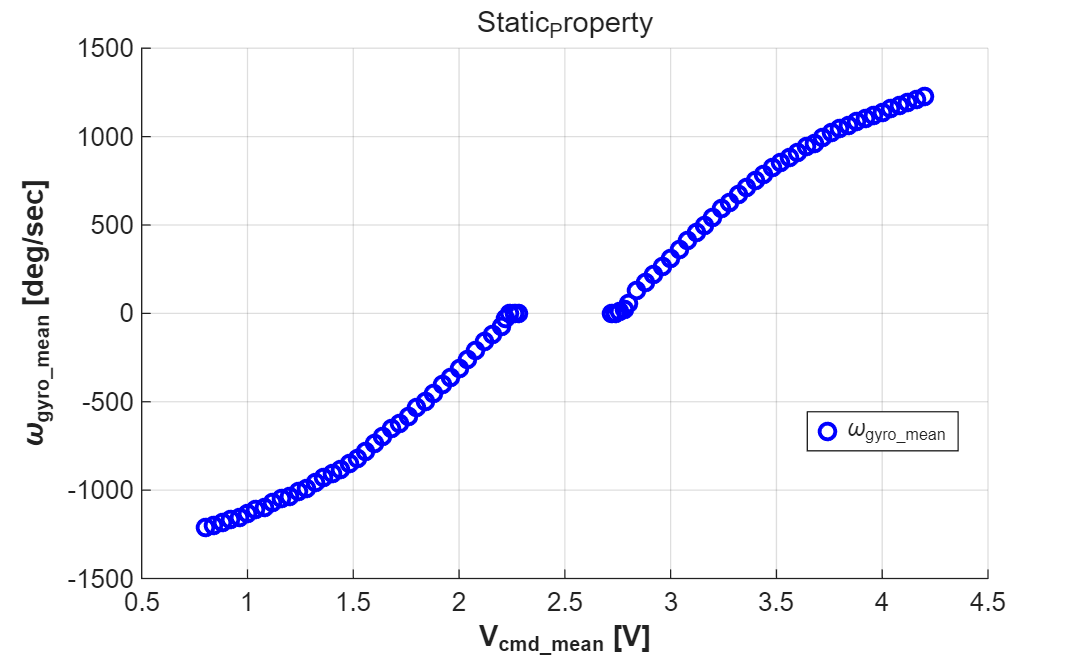

Standard Deviation: 21.3947



% plot_file('Static_data/Static_Step_-0.58.out', 1, 4);

%1.1
[Vc, Wgyro]=plot_iter(filename, 1, 2, iter); 

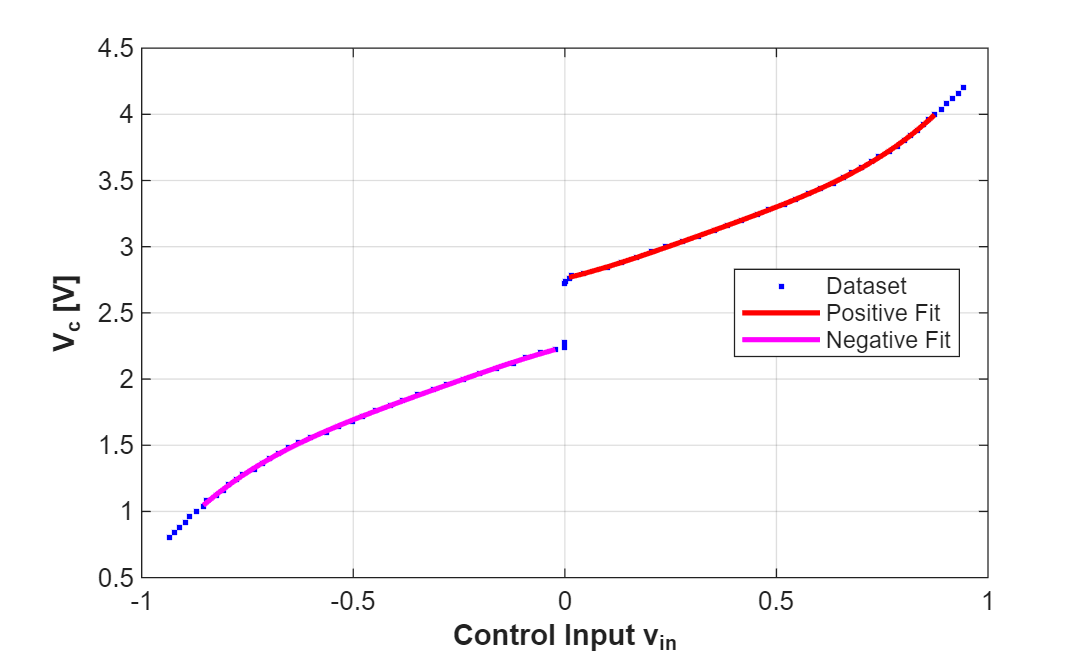


%1.2
Get_fitting_Quadratic(Vc, Wgyro); 

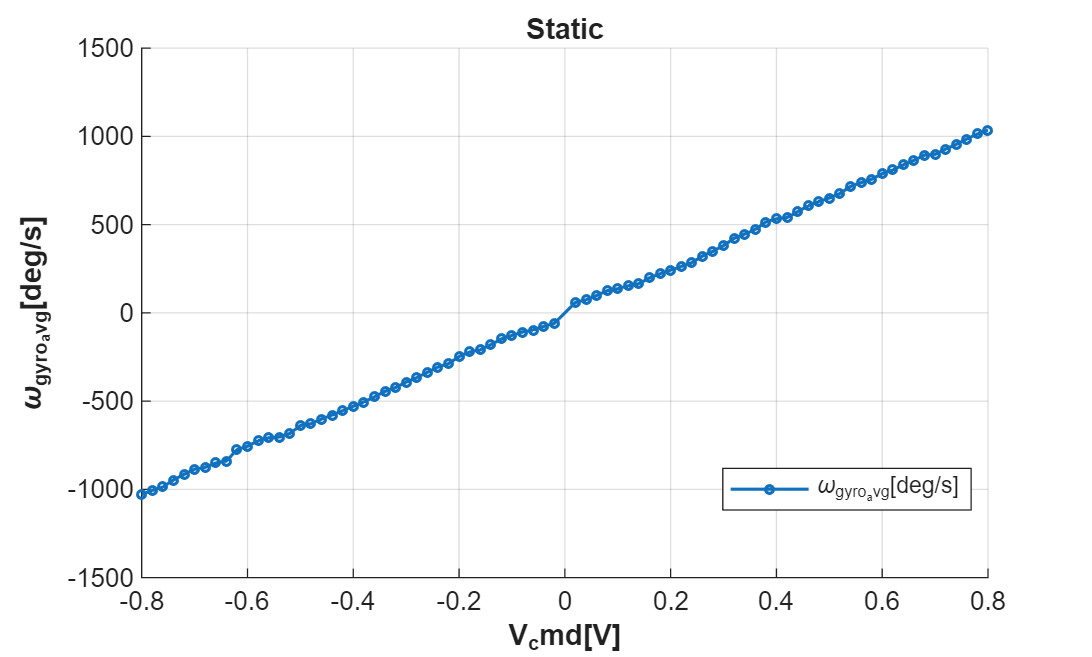


%1.3
plot_file('../data/Static_Linear/Static.out', 1, 2);

## 2. Validation - triangle

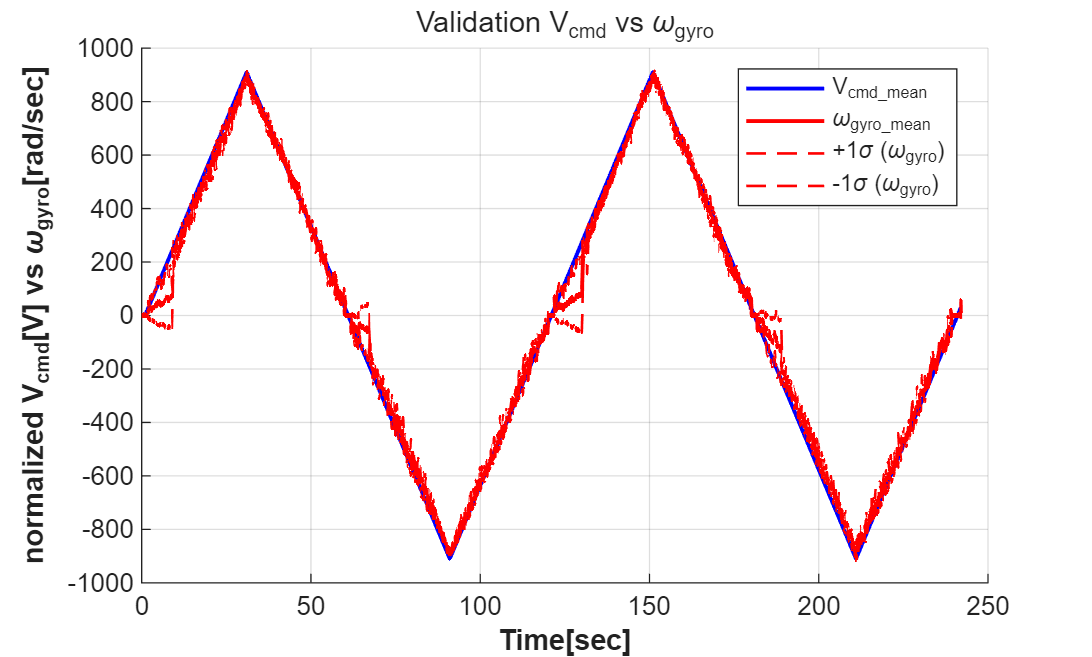

Vali_plot('tri');

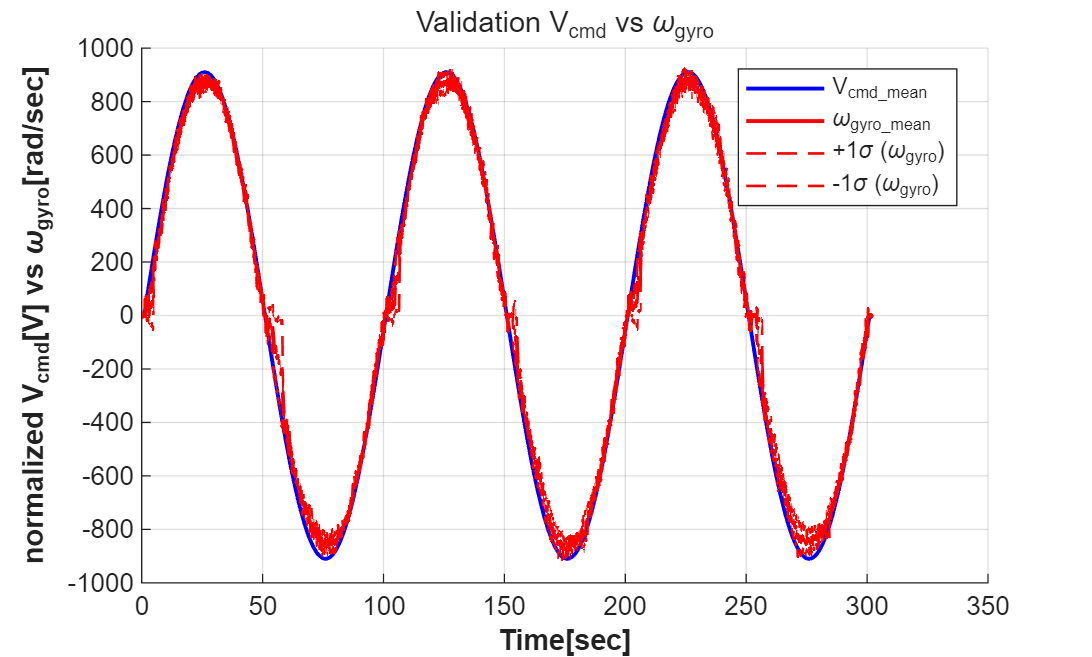

Vali_plot('sin');

## 3. Bode 

%From now on, the path is unified: 
path = '..\data\BodeMag\';

%3.1
generate_bode_plot(path);


%3.2 
% plot_bode(path); 

## 4. Obtain Transfer Function  


국소 최솟값을 찾았습니다.

기울기의 크기가 최적성 허용오차의
값보다 작기 때문에 최적화가 완료되었습니다.

<중지 기준 세부 정보>

--- Phase Fitting Result ---
wn   = 5164.2678 rad/s = 821.9187 Hz
zeta = 236.2845
DC gain = 1087.5028

--- invfreqs Result (reference) ---
 
num/den = 
 
           -5.2402
   -----------------------
   s^2 - 0.4547 s + 9.3253


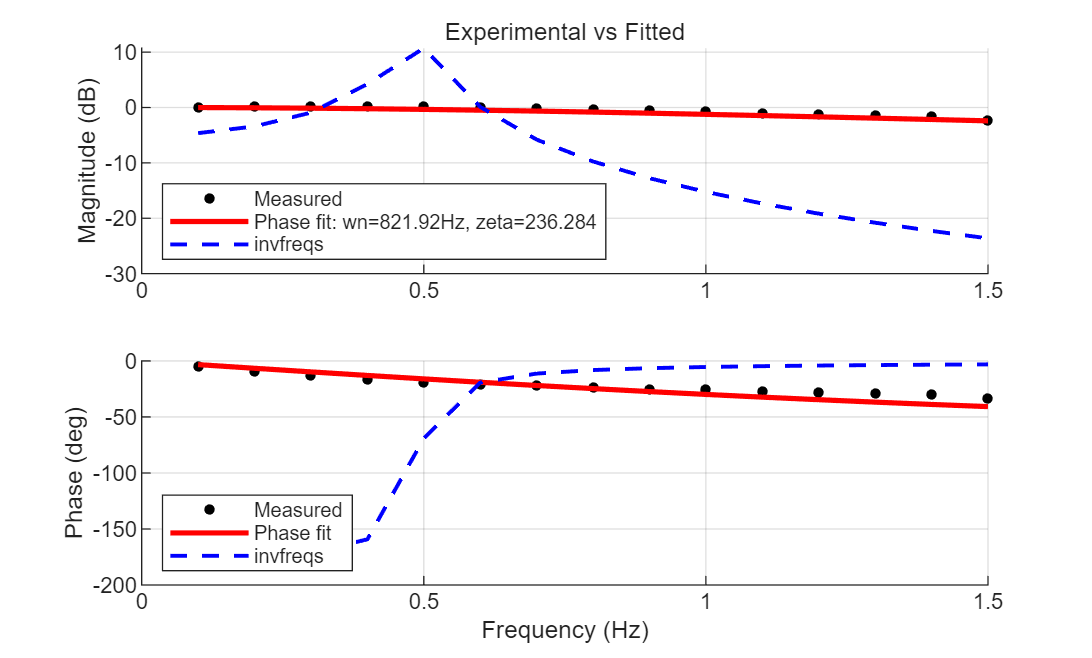

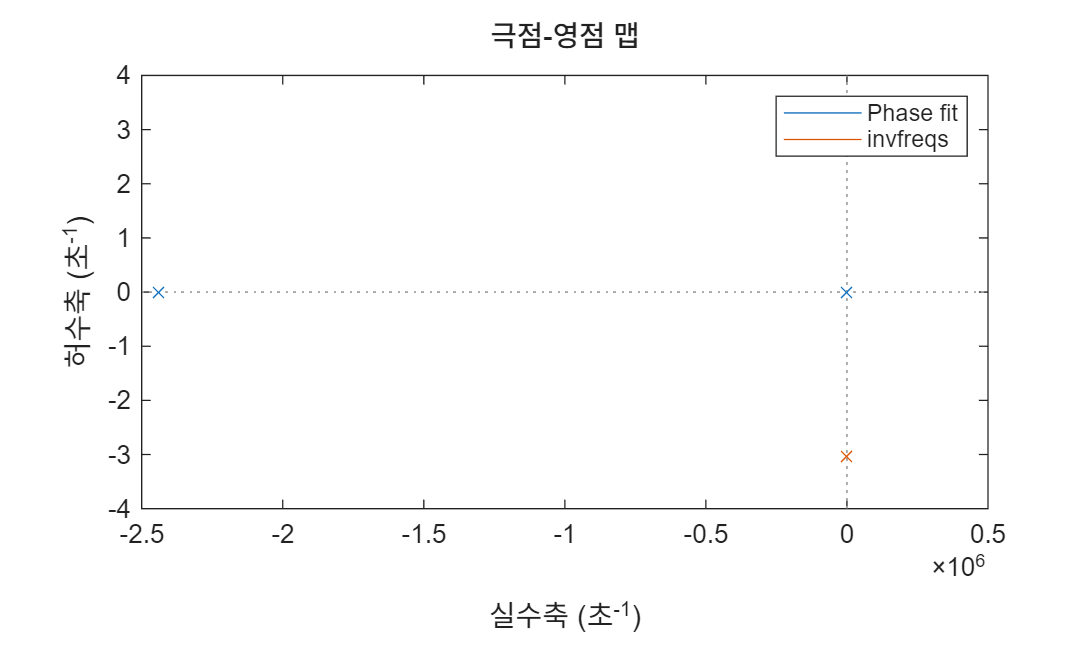

%4.1
    Trans_func(path);

%4.2
% Trans_func_valid(path); 